# [Image Classification: Bits and Cracks](https://apmonitor.com/pds/index.php/Main/BitClassification)

## Bit Classification

**Objective**: Train and test a Convolutional Neural Network to detect [drilling bit types](https://en.wikipedia.org/wiki/Drill_bit_well): [roller cone](https://petrowiki.spe.org/Roller_cone_bit_design), [Polycrystalline Diamond Compact (PDC)](https://petrowiki.spe.org/PDC_drill_bits), and spoon types.

Deep Learning (DL) is a subset of Machine Learning that uses Neural Network inspired architecture to make predictions. Convolutional Neural Networks (CNN) are a type of DL model that is effective in learning patterns in 2-dimensional data such as images. Images of drill bit types are used to train a classifier to identify common drill bit types for Oil & Gas Exploration and Horizontal Directional Drilling (HDD).

This exercise demonstrates the use of image classification to distinguish between objects in photos. Although applied to bit types, the same methods and code can be used for any type or number of objects. This example can be modified by including train and test photos in folders that are named with the object type. The code automatically takes the name of the folder as the photo label for training the classifier. An additional example of an image-based CNN is found in the [Soil Classification Case Study](https://apmonitor.com/pds/index.php/Main/SoilClassification).

For a time comparision, this Live Script was clocked on a computer with the following specs:

Processor	11th Gen Intel(R) Core(TM) i7-1195G7 @ 2.90GHz   2.92 GHz

Installed RAM	16.0 GB (15.8 GB usable)

System type	64-bit operating system, x64-based processor

This exercise uses photos of drill bit types in a compressed archive.

 [**Download: bit_photos.zip**](https://apmonitor.com/pds/uploads/Main/bit_photos.zip)

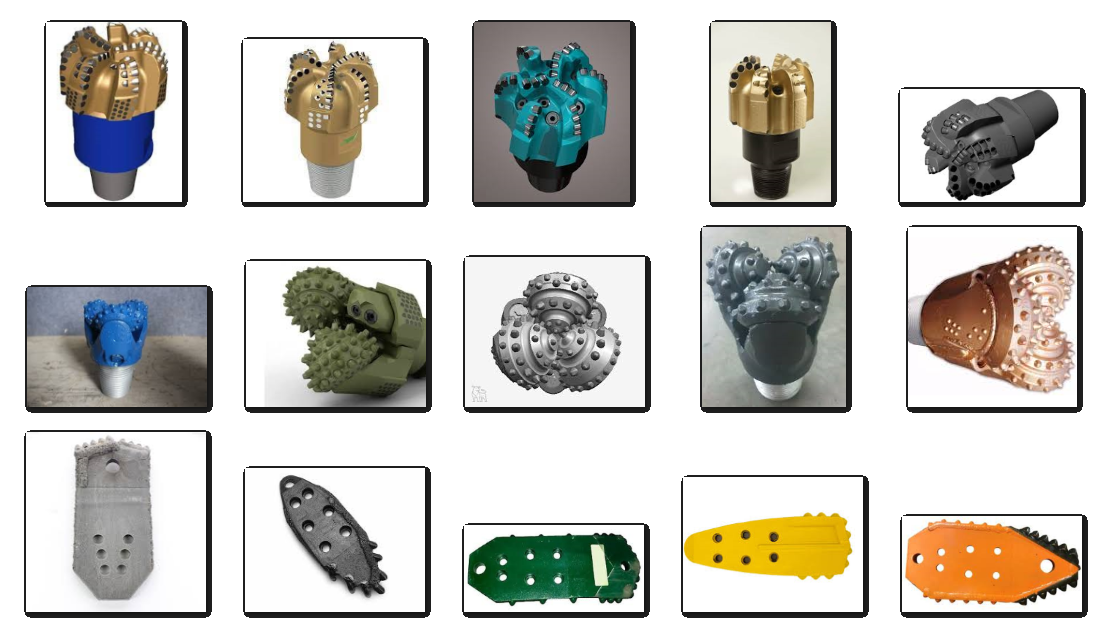

The archive contains two folders, a test folder and train folder with subdirectories corresponding to the possible drill bit types (PDC, Roller Cone, and Spoon). The images are found within each subdirectory. The tree structure of the folders is:

`  ├───test`

`  │   ├───PDC`

`  │   ├───Roller Cone`

`  │   └───Spoon`

`  └───train`

`  |   ├───PDC`

`  |   ├───Roller Cone`

`  |   └───Spoon`

The photos are imported into the MATLAB session. The first step is to process the images into a format that 1) makes the data readable to the model, and 2) provides more training material for the model to learn. For example, the *train_processor* variable scales the data so that it can be a feature (input) for the model, but also takes each images and augments it so that the model can learn from multiple variations of the same picture. It flips it horizontally, rotates it, and shifts it, and more to make sure the model learns from the shape of the bit rather than the orientation or size. 

We have a limited number of samples in our data, about 60 total. Due to the lack of data, we'll use the test data as our validation data so that we can train a better neural network. We won't test these models on unseen data. 

Below is the code for bit classification

% Download the file
url = 'http://apmonitor.com/pds/uploads/Main/bit_photos.zip';
filename = 'bit_photos.zip';
websave(filename,url);

% Unzip then deleate zip folder
unzip(filename);
delete(filename);

% Data processing
train_processor = imageDataAugmenter( ...
    'RandScale', [.8 1.2], ...
    'RandXReflection', true, ...
    'RandRotation', [-45, 145], ...
    'RandXShear', [0 45], ...
    'RandYShear', [0 45], ...
    'RandXTranslation', [-5 5], ...
    'RandYTranslation', [-5 5], ...
    'RandYReflection', true);
test_processor = imageDataAugmenter('RandScale', [0.8 1.2]);

% Load data
train = imageDatastore('train\', 'IncludeSubfolders',true, ...
    'LabelSource','foldernames','ReadFcn',@imread);
train_preprocess = augmentedImageDatastore([255,255],train, 'DataAugmentation', train_processor);
test = imageDatastore('test\', 'IncludeSubfolders', true,...
    'LabelSource', 'foldernames', 'ReadFcn', @imread);
test = augmentedImageDatastore([255,255],test, 'DataAugmentation', test_processor);

The [imageDatastore](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) function creates an object to manage a collection of image files. 

### **Build Neural Network **

**Programmatic Approach **

Change the number of training epochs and other options to modify the training neural network. Know that the more training epochs there are, the longer the training process will take. Based on the size of the dataset, size of the network and hyperparameters chosen, training time of the network may vary. We trained this network locally, but if more compute resources are needed, these computations could be performed using cluster or cloud computing or using local NVIDIA GPUs. Deep Learning Toolbox automatically detects and uses compatible GPUs if they are locally available.The network below is a starting point and should take roughly 10 minutes if ran on a local CPU. 

num_training_epochs = 20;

Build the Neural Network based on the values above

layers = [imageInputLayer([255 255 3]); % Specifies the dimensions of the input data
            convolution2dLayer([3 3],20); % Applies 20 filters of size 3x3 to the input data
            reluLayer(); % ReLU sets negative values to zero and keeps positive values unchanged
            maxPooling2dLayer([2 2]); % Max pooling reduces the spatial dimensions by selecting the maximum value within each 2x2 region
            fullyConnectedLayer(3); % Creates a fully connected layer with 3 neurons
            softmaxLayer(); % Converts output values to a probability distribution
            classificationLayer(); % Assigns the classification based upon the probabilities
            ];

options = trainingOptions("adam", ... % Use the Adam optimizer as the optimization algorithm
    InitialLearnRate=0.001, ... % Set the initial learn rate
    SquaredGradientDecayFactor=0.99, ... % Sets the squared gradient term to decay by 1% at each time step (prevents over fluctuation)
    MaxEpochs=num_training_epochs, ... % Sets the maximum number of times the classifier will go through the entire dataset 
    MiniBatchSize=24, ... % Sets the data to be split into smaller batch sizes of 24
    Verbose=true,... % Displays training progress during training
    ValidationData=test, ...
    Plots="training-progress");

### Train Neural Network

**Programmatic Approach**

(estimated time: 5 minutes)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       25.00% |       33.33% |      44.6262 |    8500.8643 |          0.0010 |
|      20 |          40 |       00:00:53 |       50.00% |       33.33% |     718.4071 |    1454.1216 |          0.0010 |
|======================================================================================================================|
Training finished: Max epochs completed.


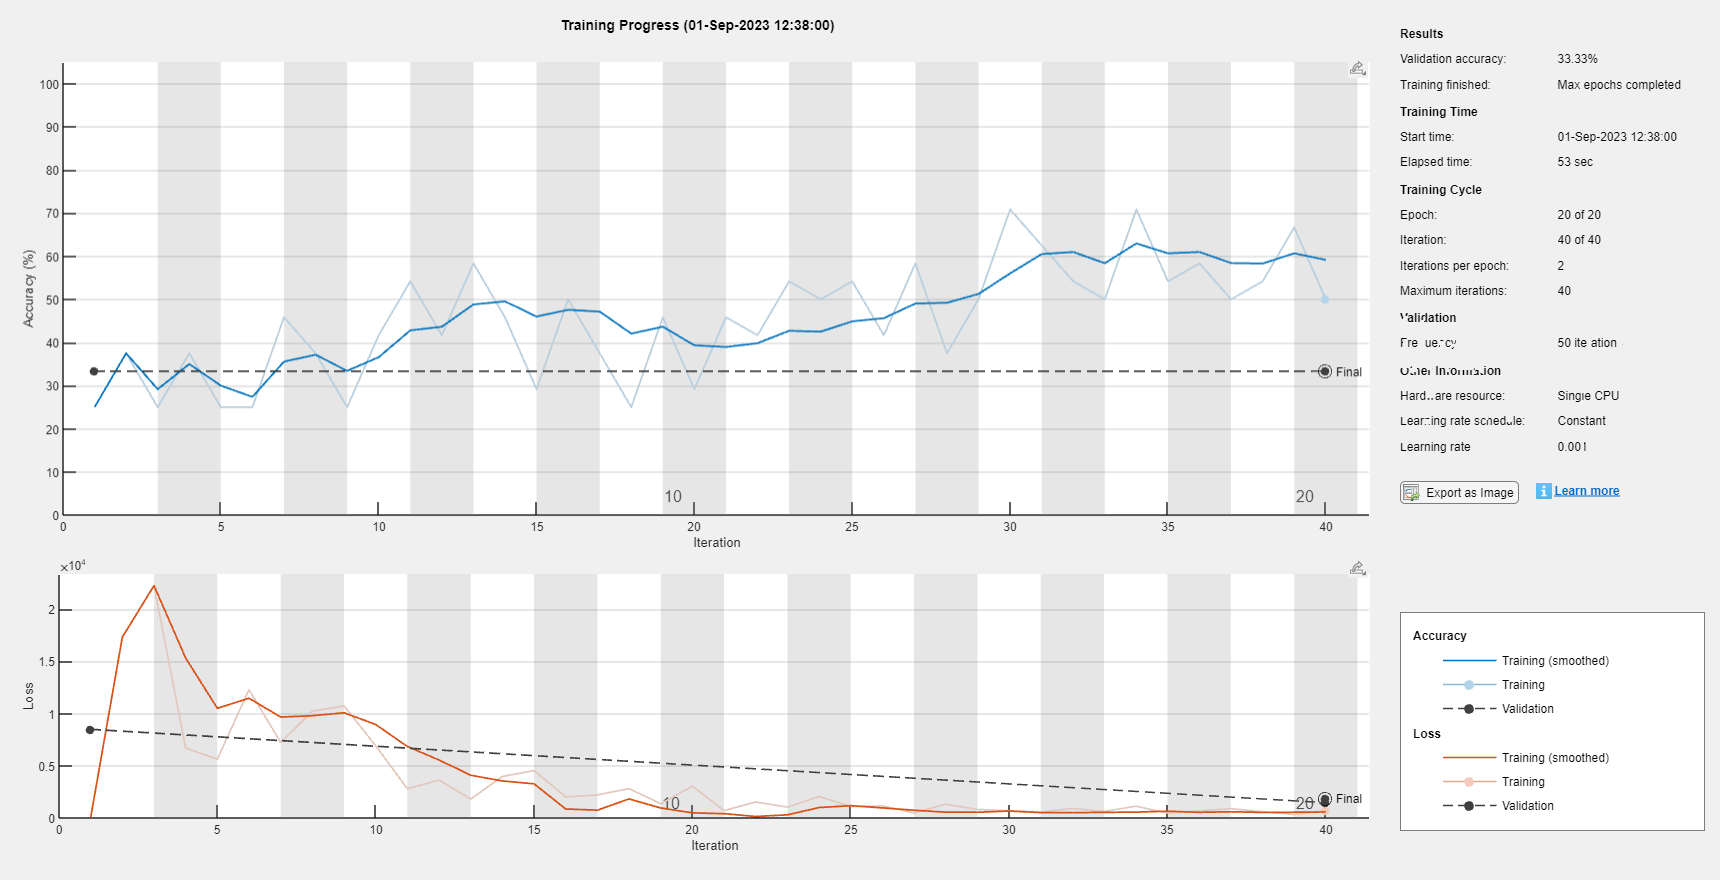

[net,~] = trainNetwork(train_preprocess, layers, options);

### **Build Neural Network with the Deep Network Designer**

**Interactive Approach**

In these next two sections it will be shown how to build and train the same neural network built above, interactively with the Deep Network Designer app. 

Click on Apps in the Ribbon. Click on the Deep Network Designer under the Machine Learning and Deep Learning section. When the pop-up comes up, click New on the Blank Network. Next, you can drag and drop the layers from the left hand side to the Designer tab. Once all layers are set in the Designer tab, link the layers in order with the arrows. You can change the number of layers to your desire (remember the more layers in your neural network, the more computing power required). When using a fully connected layer be sure to change the output size to 3 because there are three classification possibilities. Also, change input size to 255,255,3 when using the image input layer so that it matches the image sizes. 

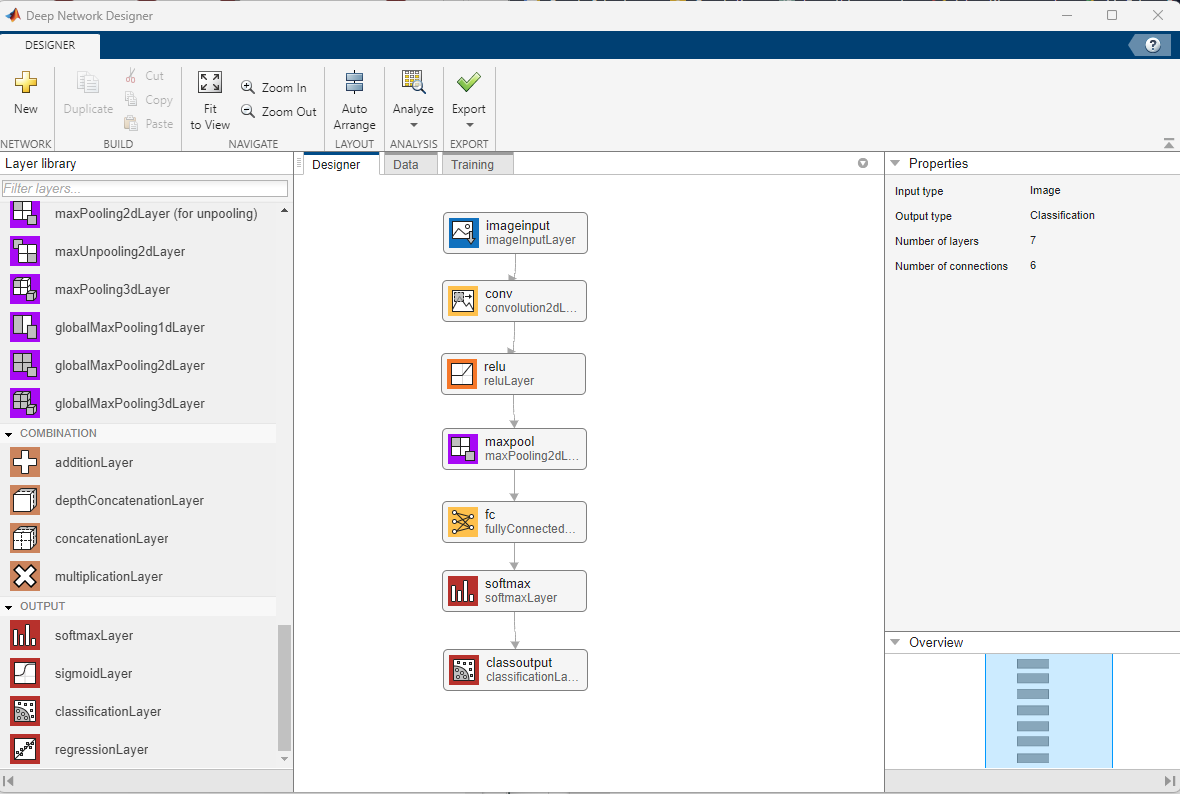

For more details on how to design the neural network, refer to the Soil Classification case study.

### **Train Neural Network with the Deep Network Designer**

**Interactive Approach**

Click on the Data tab in Deep Network Designer and click Import Data in the top left. Click Import Custom Data. On the pop-up, select train_preprocess for the training data and click test for the Validation data. Now click on the training tab and click Training Options in the top left. 

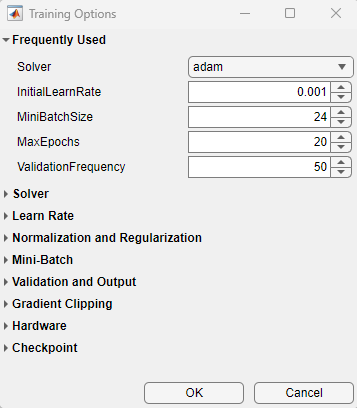

Change the solver to adam, MiniBatchSize to 24, MaxEpochs to 20 and then click ok. Now click Train. Use the Export button to automatically generate the code or to export the trained neural network.

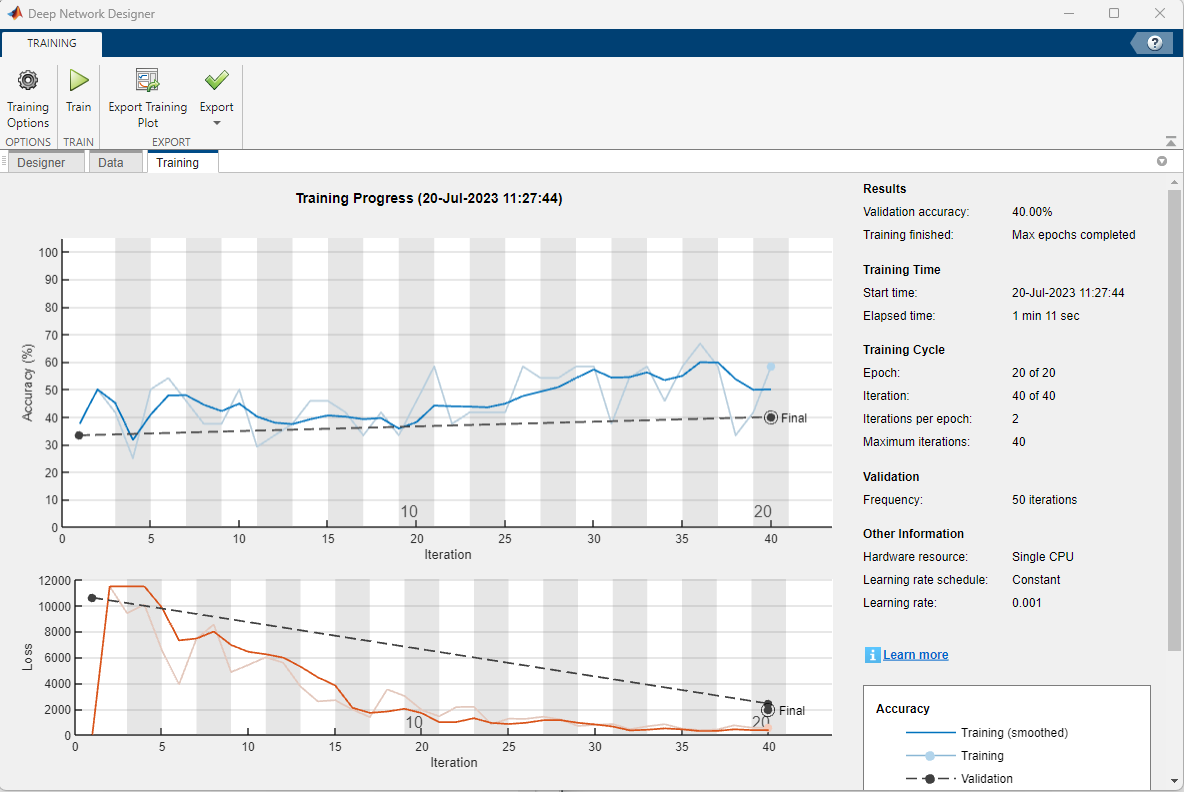

The Deep Network Designer app is part of the Deep Learning Toolbox. To learn more about this app see [Get Started with Deep Network Designer](https://www.mathworks.com/help/deeplearning/gs/get-started-with-deep-network-designer.html). 

### Test Neural Network

Grab random test drill bit and predict the type.

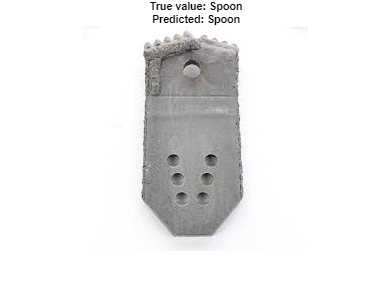

% Grab random picutre
btype = ["PDC", "Roller Cone", "Spoon"]; % possible output values
bbtype = ["PDC", "Roller_Cone", "Spoon"]; % possible output values
rng('shuffle');
i=randi(3);
j=randi(5);
b = btype(i);
bb = bbtype(i);
im = strcat(lower(strrep(strcat(bb,'_',num2str(j),'.jpg'),'',"")));
test_image_filepath = fullfile('./test',b,im);

% Read image
image_fp = test_image_filepath;
ime = imread(image_fp); % load image

% Modify image to fit Neural Network
im = double(imresize(ime,[255 255]));

% Display image with prediction
true_value = regexp(image_fp, "(PDC)|(Roller Cone)|(Spoon)", 'match');
figure('Position', [0,0,1000,1000])
imshow(ime);

% Create title string and display title
label = "True value: " + string(true_value{1}) + "\n" + "Predicted: " + string(net.classify(im));
label = compose(label);
bit_title = title(label);

% Adjust the title position 
titlePos = get(bit_title, 'Position'); 
titlePos(2) = -0.1; % Adjust the title
set(bit_title, 'Position', titlePos, 'FontSize', 8);

The validation accuracy as well as individual testing shows that there are misclassifications.

Here are a few things that can improve the accuracy for this application:

- **More photos!** This is the most important thing, Machine Learning typically requires many photos that are representative of what the classifiers see. At this point, there are not nearly enough photos for the model to learn each bit type.

- **Background Clutter.** Most of the images in this set have the background removed. To train a classifier to identify bit types in the field, more photos with realistic backgrounds are needed. Synthetic backgrounds can also be added.

- **Hyperparameter Optimization.** To make the best model, the best parameters must be selected to maximize the accuracy (hyperparameter optimization). Hyperparameters can be adjusted throught the Experiment Manager, further details can be found in this [link](https://www.mathworks.com/help/deeplearning/experiment-manager.html).

## Crack Classification

Replace the photos in the bit classification case study to build a classifier to distinguish photos of concrete with a crack (Positive) or no crack (Negative).

 [**Download: concrete_cracks.zip**](https://apmonitor.com/pds/uploads/Main/concrete_cracks.zip)

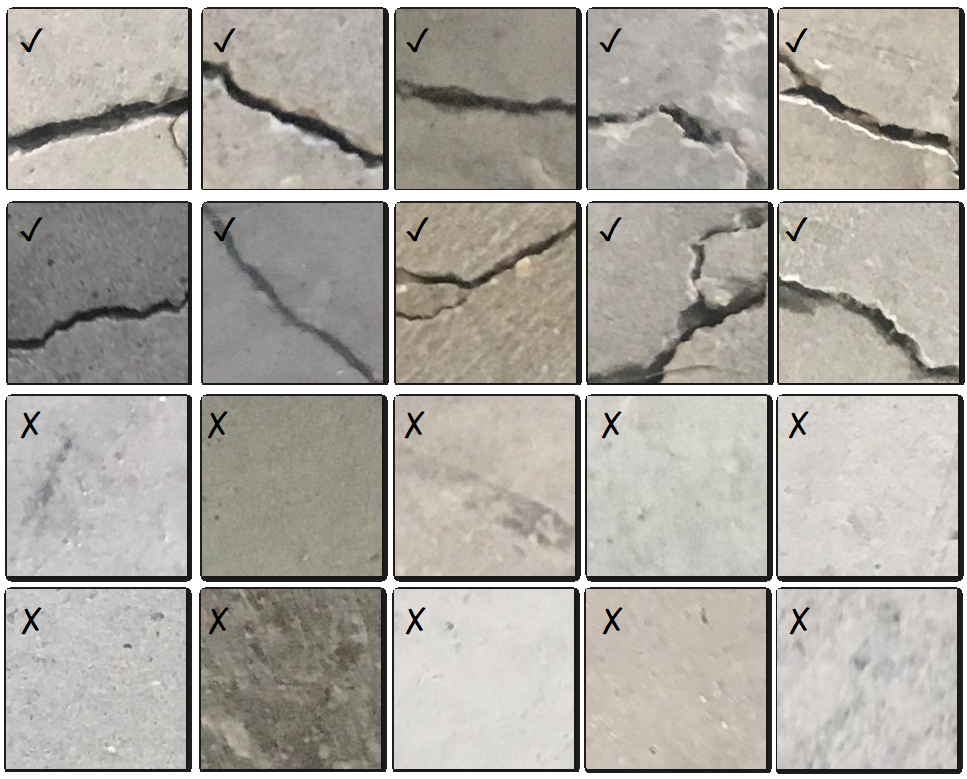

The images are found within each subdirectory. The tree structure of the folders is:

`  ├───test`

`  │   ├───Positive`

`  │   └───Negative`

`  └───train`

`      ├───Positive`

`      └───Negative`

The dataset is divided into two (negative and positive) crack image folders for image classification. Each train folder has 500 images with a total of 1000 images with 227 x 227 pixels with RGB channels. The test folders have 100 images from the full image set for a total of 200 test images. Again we'll be using the test data as our validation data to train a better neural network. 

% Clean the workspace and the folders from above
rmdir('train','s');
rmdir('test','s');

url = 'http://apmonitor.com/pds/uploads/Main/concrete_cracks.zip';
filename = 'concrete_cracks.zip';
outfilename = websave(filename,url);

% Unzip then delete zip folder
unziped_folder = unzip(filename);
delete(filename);

% Data processing
train_processor = imageDataAugmenter( ...
    'RandScale', [.8 1.2], ...
    'RandXReflection', true, ...
    'RandRotation', [-45, 145], ...
    'RandXShear', [0 45], ...
    'RandYShear', [0 45], ...
    'RandXTranslation', [-5 5], ...
    'RandYTranslation', [-5 5], ...
    'RandYReflection', true);
test_processor = imageDataAugmenter('RandScale', [0.8 1.2]);

% Load data
train = imageDatastore('train\', 'IncludeSubFolders', true, ...
    'LabelSource','foldernames', 'ReadFcn',@imread);
train_preprocess_con = augmentedImageDatastore([128,128],train, 'DataAugmentation', train_processor);
test = imageDatastore('test\', 'IncludeSubfolders', true,...
    'LabelSource', 'foldernames', 'ReadFcn', @imread);
test = augmentedImageDatastore([128,128],test, 'DataAugmentation', test_processor);

### **Build Neural Network**

Change the number of training epochs and other options to modify the training neural network. Know that the more training epochs and neural network layers there are, the longer the training process will take. Based on the size of the dataset, size of the network and hyperparameters chosen, training time of the network may vary. We trained this network locally, but if more compute resources are needed, these computations could be performed using cluster or cloud computing or using local NVIDIA GPUs. Deep Learning Toolbox automatically detects and uses compatible GPUs if they are locally available.The network below is a starting point and should take roughly 10 minutes if ran on a local CPU. 

num_conv_layers = 2;
layer_size = 16;
num_training_epochs = 5;

Build the Neural Network based on the values above

% Create a cell for the layers
layers = cell((num_conv_layers+1)*3+4,1);
layers{1} = imageInputLayer([128 128 3]);
layers{2} = convolution2dLayer([3 3],layer_size);
layers{3} = reluLayer();
layers{4} = maxPooling2dLayer([2 2]);

% Add additional convolutional layers based on num_conv_layers
for i = 1:num_conv_layers-1 
    layers{i*3 + 2} = convolution2dLayer([3 3],layer_size);
    layers{i*3 + 3} = reluLayer();
    layers{i*3 + 4} = maxPooling2dLayer([2 2]);
end

% Reduce dimensionality
layers{end-5} = flattenLayer();

layers{end-4} = fullyConnectedLayer(layer_size);
layers{end-3} = reluLayer();

% Add final dense layer
layers{end - 2} = fullyConnectedLayer(2);
layers{end - 1} = softmaxLayer();
layers{end} = classificationLayer();

% Convert the cell into a regular array
layers = [layers{:}];

options = trainingOptions("adam", ...
    SquaredGradientDecayFactor=0.99, ...
    InitialLearnRate=0.001, ...
    MaxEpochs=num_training_epochs, ...
    MiniBatchSize=32, ...
    Verbose=true,...
    Plots="training-progress",...
    ValidationData=test ...
    );

### Train Neural Network 

(estimated time: 5 minutes)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       50.00% |       50.00% |      11.0589 |    4447.9575 |          0.0010 |
|       2 |          50 |       00:00:47 |       40.62% |       50.00% |       0.6934 |       0.6931 |          0.0010 |
|       4 |         100 |       00:01:29 |       21.88% |       50.00% |       0.6943 |       0.6931 |          0.0010 |
|       5 |         150 |       00:02:12 |       46.88% |       50.00% |       0.6933 |   

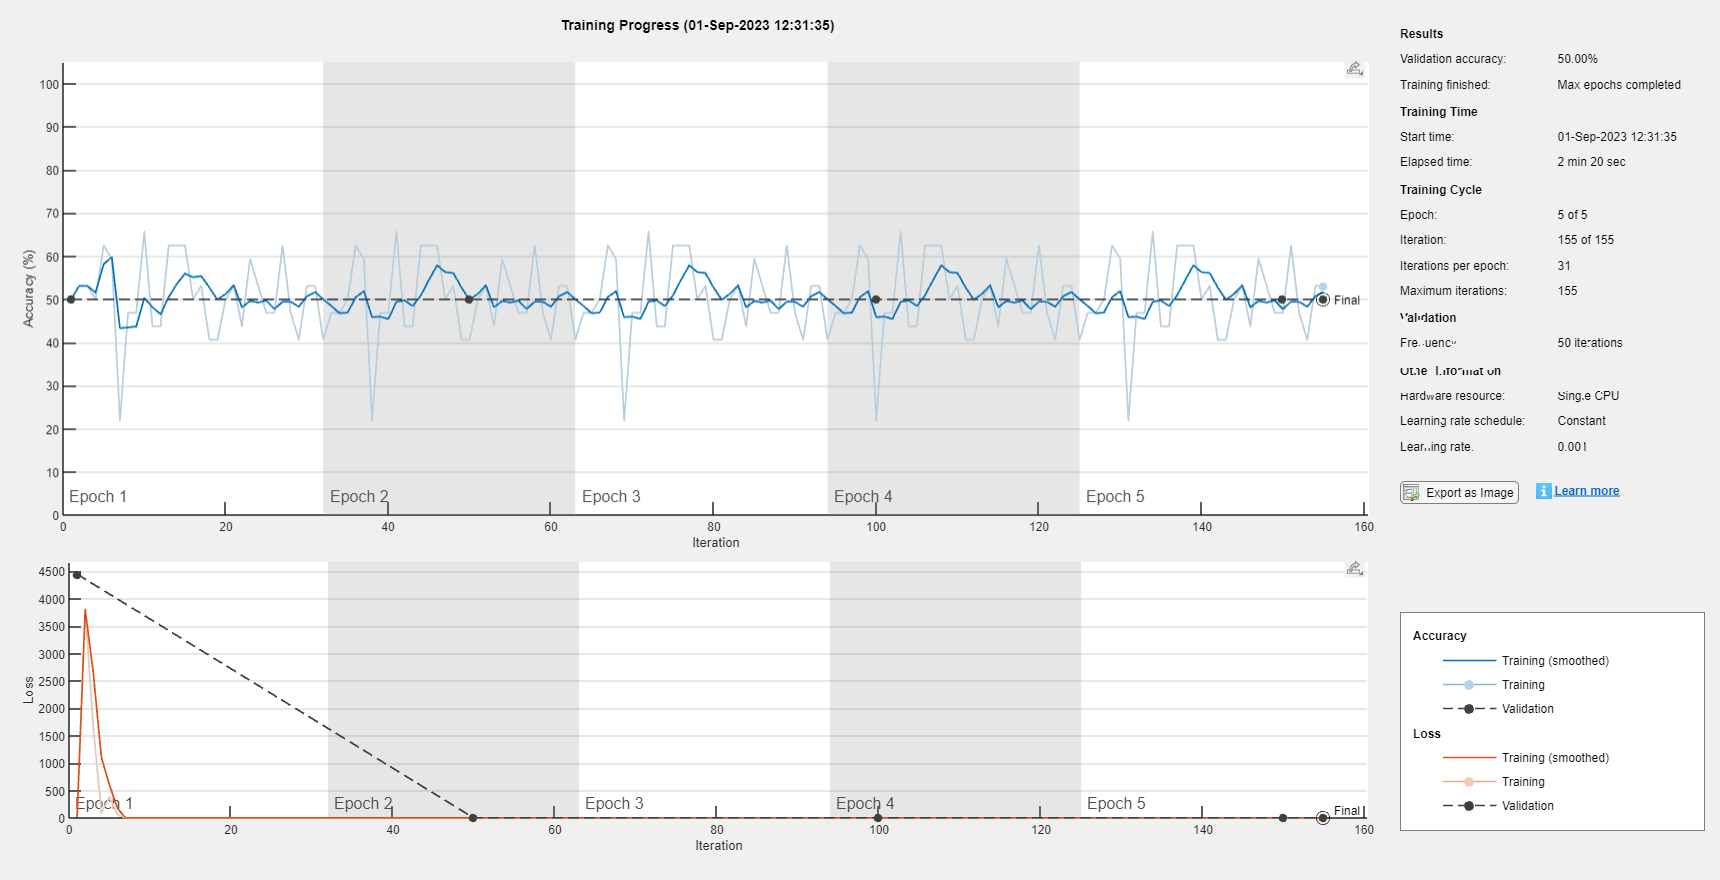

[net,info] = trainNetwork(train_preprocess_con, layers, options);

### Test Neural Network

Grab random test image and predict the type.

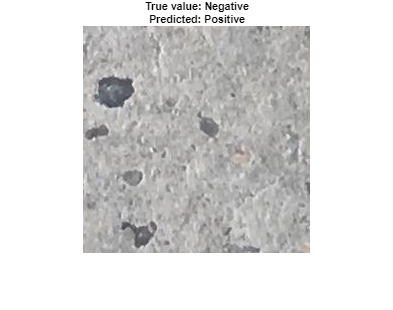

btype = ["Positive", "Negative"]; % possible output values
rng('shuffle');
i=randi(2);
j=randi([19901,20000]);
b = btype(i);
im = strcat(lower(strrep(strcat(num2str(j),'.jpg'),'',"")));
test_image_filepath = fullfile('./test',b,im);

% Show image
image_fp = test_image_filepath;
ime = imread(image_fp); % load image

% Modify image for Neural Network
im = double(imresize(ime,[128 128]));

% Display image with prediction
true_value = regexp(image_fp, "(Positive)|(Negative)", 'match');
figure('Position', [0,0,1000,1000])
imshow(ime);

% Create title string and display title
label =  "True value: " + string(true_value{1}) + "\n" + "Predicted: " + string(net.classify(im));
label = compose(label);
crack_title = title(label);

% Adjust the title position 
titlePos = get(crack_title, 'Position'); 
titlePos(2) = -0.1; % Adjust the title
set(crack_title, 'Position', titlePos, 'FontSize', 8);

The validation accuracy as well as individual testing shows that there are many misclassifications.

Here are a few things that can improve the accuracy for this application:

- **More photos!** This is the most important thing, Machine Learning typically requires many photos that are representative of what the classifiers see. At this point, there are not nearly enough photos for the model to learn each bit type.

- **Background Clutter.** Most of the images in this set have the background removed. To train a classifier to identify bit types in the field, more photos with realistic backgrounds are needed. Synthetic backgrounds can also be added.

- **Hyperparameter Optimization.** To make the best model, the best parameters must be selected to maximize the accuracy (hyperparameter optimization). Hyperparameters can be adjusted throught the Experiment Manager, further details can be found in this [link](https://www.mathworks.com/help/deeplearning/experiment-manager.html).